# Longitudinal Vehicle - Main Script

This script runs selected simulation cases and plots simulation results.

## Open Model

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

% Load model parameters.
Vehicle1D_harness_setup

% Set referenced subsystem.
set_param(mdl + "/Longitudinal Vehicle", ...
  ReferencedSubsystem = "Vehicle1D_refsub_Driveline")

## Vehicle Property

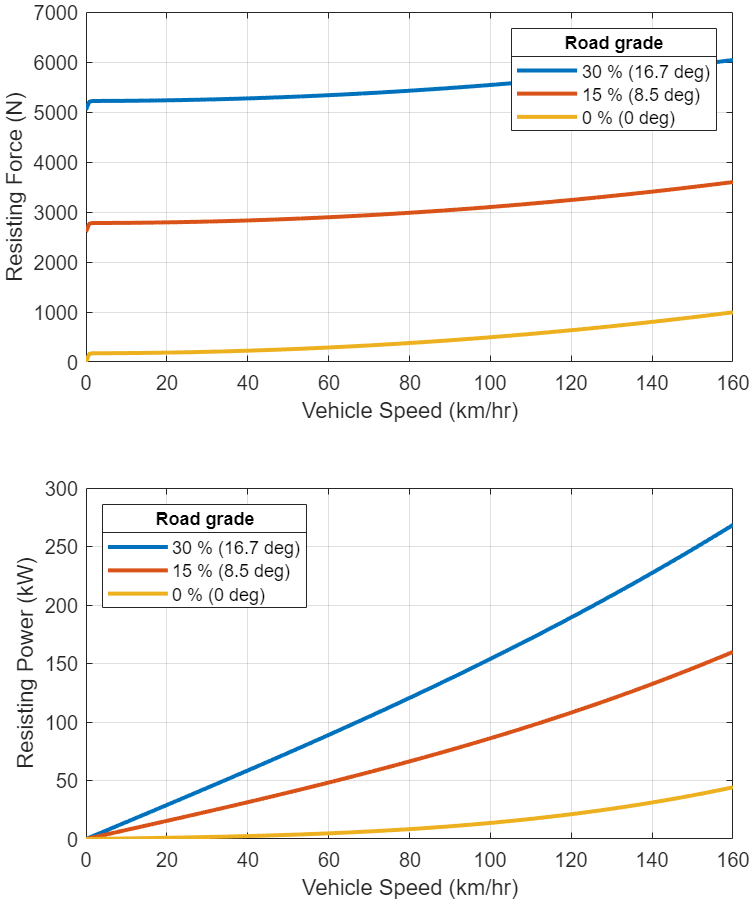

% Select subsystem
set_param(0, CurrentSystem = mdl+"/Longitudinal Vehicle")

% Select block
set_param(gcs, CurrentBlock = "Longitudinal Vehicle")

block_info = Vehicle1DUtility.getVehicle1DDrivelineBlockInfo(gcbh);

fig = Vehicle1DUtility.plotRoadLoad( ...
  "VehicleMass_kg", block_info.M_e_kg, ...
  "RoadLoadA_N", block_info.A_rl_N, ...
  "RoadLoadB_N_per_kph", block_info.B_rl_N_per_kph, ...
  "RoadLoadC_N_per_kph2", block_info.C_rl_N_per_kph2, ...
  "GravitationalAcceleration_m_per_s2", block_info.grav_m_per_s2, ...
  "VehicleSpeedVector_kph", linspace(0, 160, 200), ...
  "RoadGradeVector_pct", [30, 15, 0] );
fig.Position(3:4) = [500 600];  % width height

## Run Simulations

% Set up external input signals
vehSigBuilder = Vehicle1D_InputSignalBuilder;
inputPatterns = [
  "Constant"
  "Coastdown"
  "Brake3"
  "RoadGrade3"
  "DriveAxle"
];
numSim = numel(inputPatterns);

% Create SimulationInput object for each simulation
clear simIn
%simIn(1:numSim) = Simulink.SimulationInput(mdl);  % error in R2022a.
simIn(1:numSim) = Simulink.SimulationInput(char(mdl));
for idx = 1 : numSim
  inpData = feval(inputPatterns(idx), vehSigBuilder);
  simIn(idx) = setModelParameter(simIn(idx), "StopTime",num2str(inpData.Options.StopTime_s));
  simIn(idx) = setVariable(simIn(idx), "vehicle_InputSignals", inpData.Signals);
  simIn(idx) = setVariable(simIn(idx), "vehicle_InputBus", inpData.Bus);
  simIn(idx) = setVariable(simIn(idx), "initial.vehicle_speed_kph", ...
                inpData.Options.InitialVehicleSpeed_kph);
end

% Run simulations
simOut = sim(simIn, UseFastRestart="on", ShowProgress="on");

[25-Apr-2022 14:30:09] Running simulations...
[25-Apr-2022 14:30:11] Completed 1 of 5 simulation runs
[25-Apr-2022 14:30:12] Completed 2 of 5 simulation runs
[25-Apr-2022 14:30:12] Completed 3 of 5 simulation runs
[25-Apr-2022 14:30:13] Completed 4 of 5 simulation runs
[25-Apr-2022 14:30:14] Completed 5 of 5 simulation runs


## Simulation Results

Constant


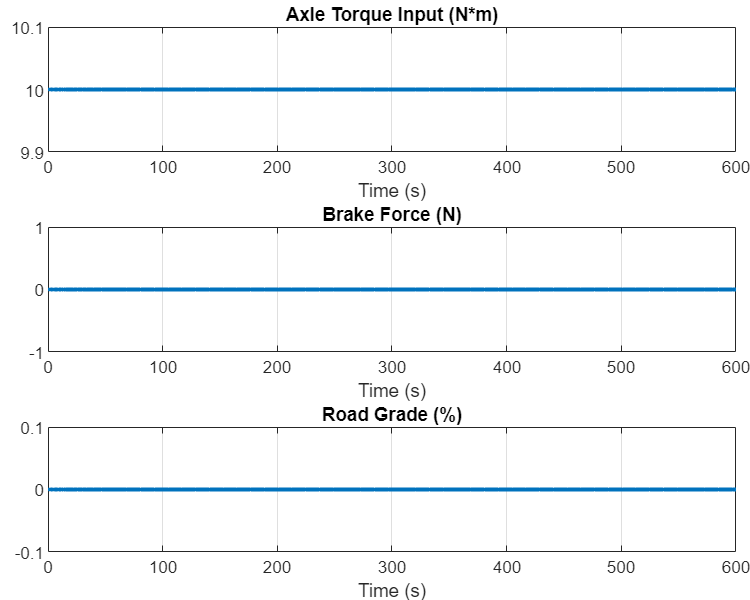

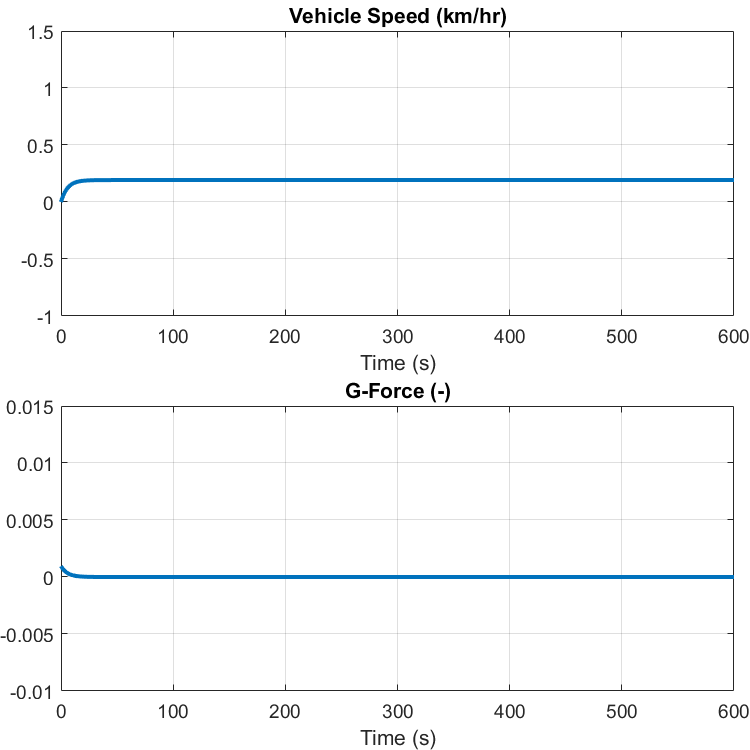

Coastdown


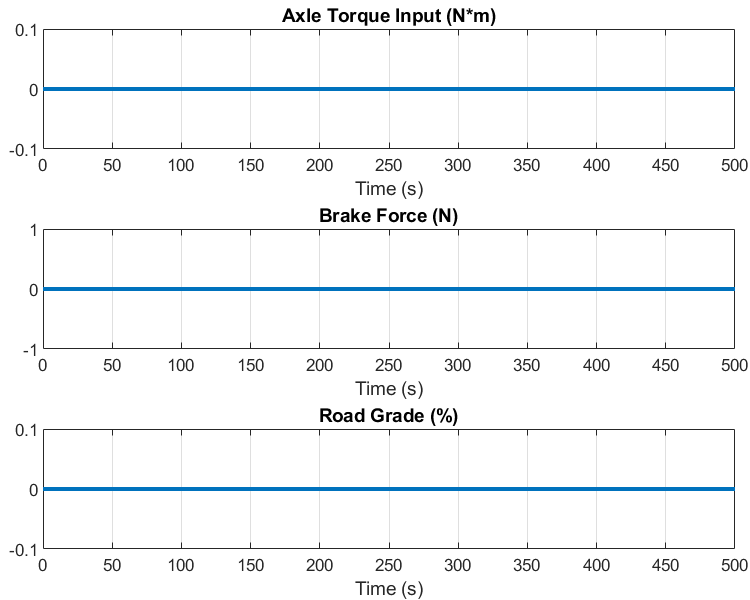

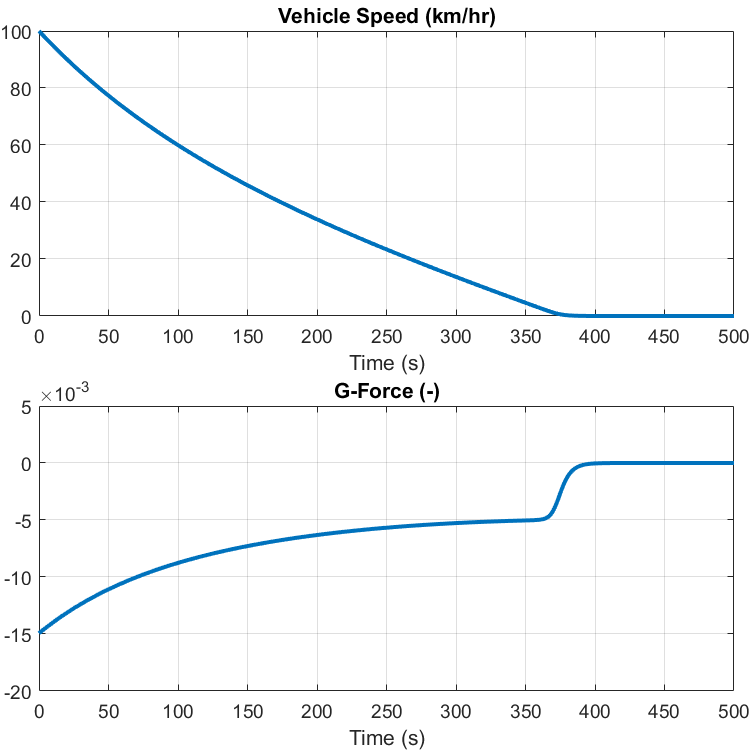

Brake3


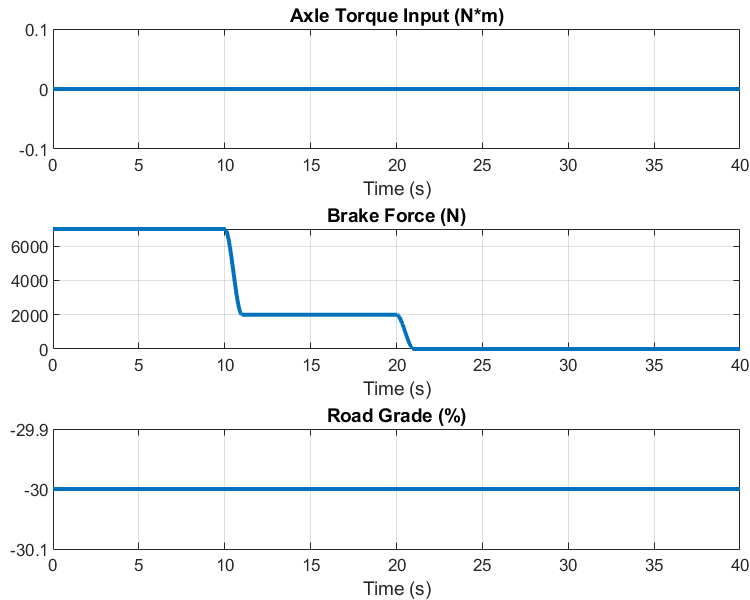

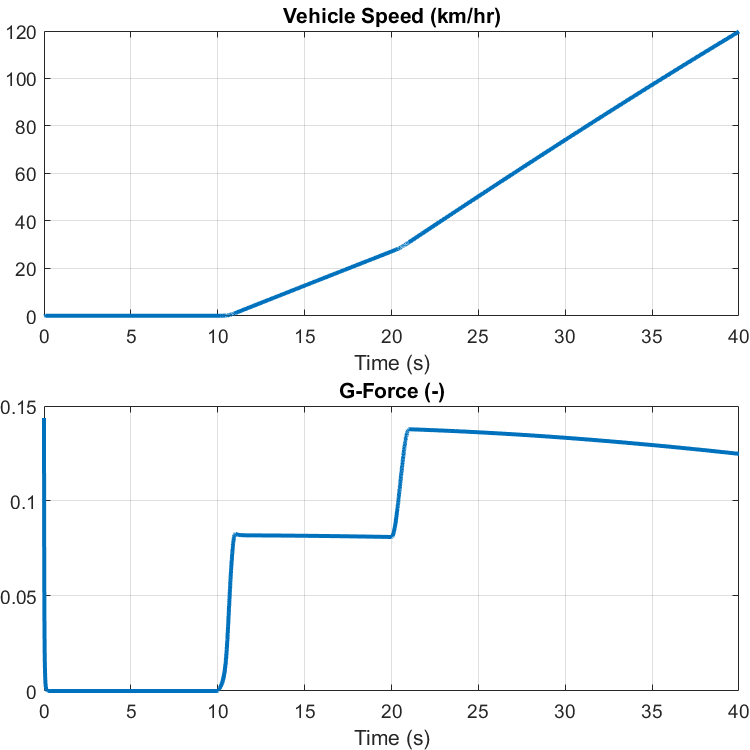

RoadGrade3


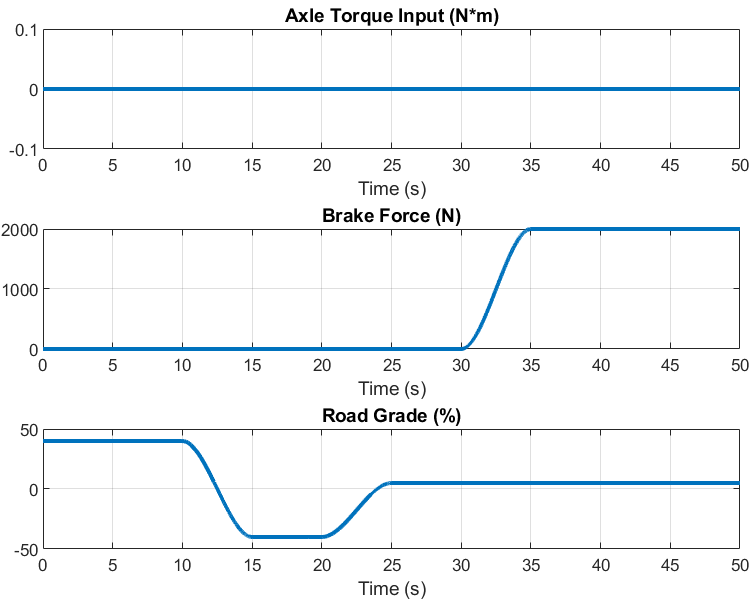

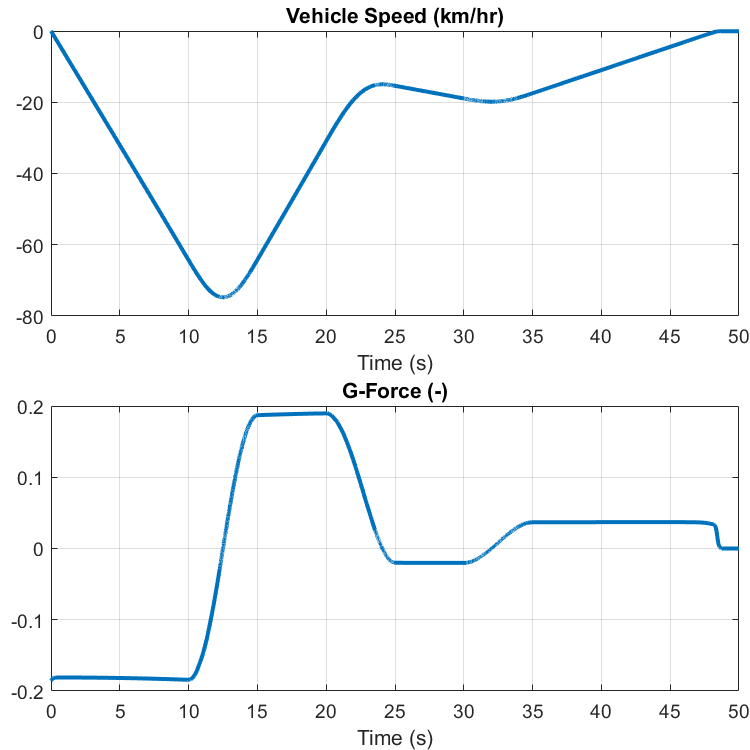

DriveAxle


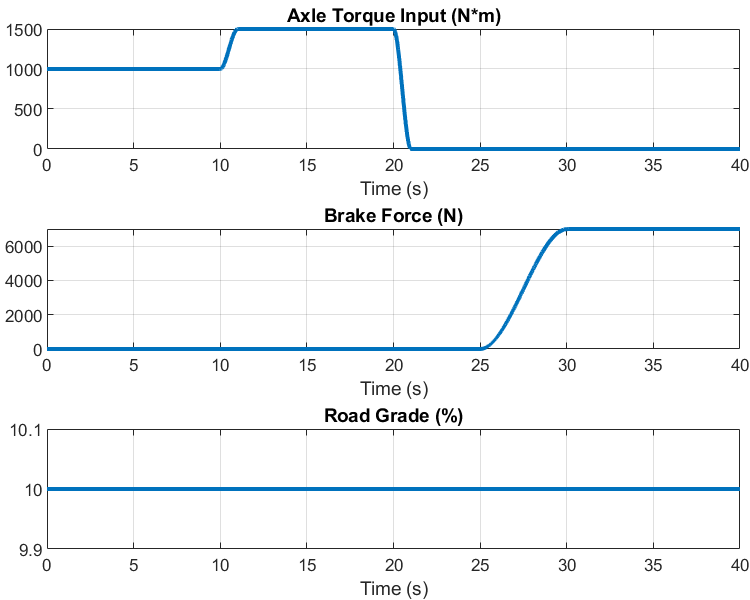

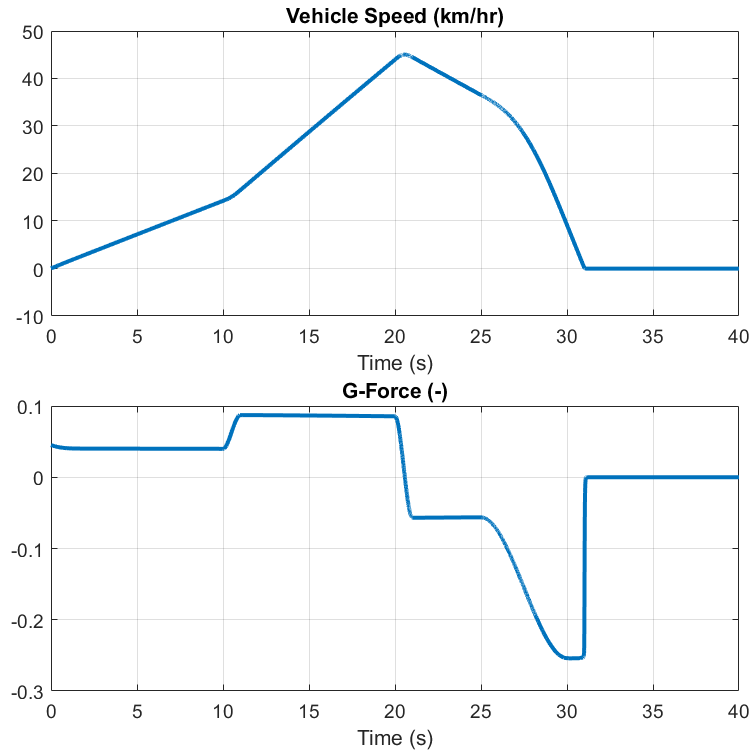

for idx = 1 : numSim
  disp(inputPatterns(idx))
  Vehicle1D_plot_results(simOut(idx).logsout)
end

*Copyright 2020-2022 The Mathworks, Inc.*